# Lecture 8: Bode Plots & Nyquist Stability

- Phase Margin, Gain Margin, Modulus Margin

- Nyquist stability

We seek to analyze a system $G\left(s\right)=\frac{1}{{s\left(s+1\right)}^{2\;} }$ with a feedback controller under the presence of disturbances $d\left(s\right)$ and sensor noise $n\left(s\right)$.

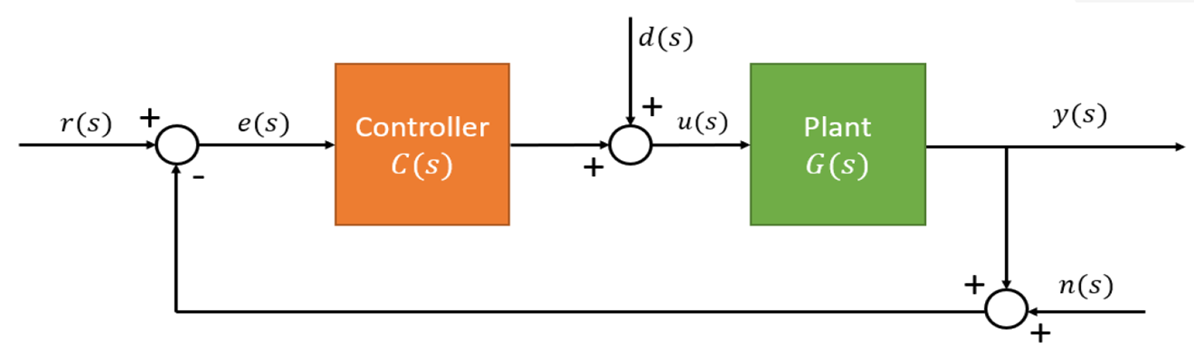

## Transfer functions

Useful transfer functions to remember are:

- Open-loop $L=\textrm{CG}$

- Closed-loop $T=\frac{L}{1+L}$ (also known as "complementary sensitivity" and measures error due to noise $=\frac{e}{n\;}$)

- Sensitivity $S=\frac{1}{1+L}$ (measures reference tracking error $=\frac{e}{r\;}$)

- Process sensitivity $\textrm{PS}=\frac{G}{1+L}$ (measures error due to disturbances $=-\frac{e}{d}$)

## Bode Plots: GM, PM, $\omega_c$

Gain Margin (GM) and Phase Margin (PM) are measures how how 'close' the closed-loop system is from instability. These values can be determined from the bode plot of the open-loop $L\left(j\omega \;\right)$. GM is measured when $\angle \;L\left(j\omega \;\right)=-{180}^{0\;}$ and PM is measured when $|L\left(j\omega \right)|=0\textrm{dB}$. The crossover frequency (=bandwidth) is also the frequency at which $|L\left(j\omega \;\right)|=0\textrm{dB}=1$.

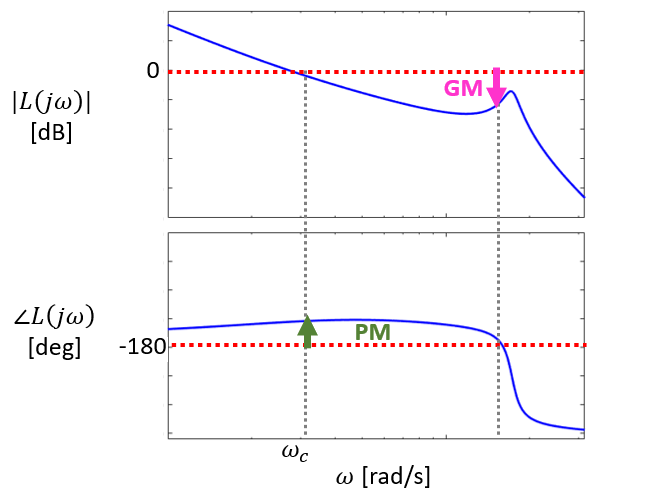

Rules of thumb are: GM$\ge 6$dB and PM$\ge {30}^{0\;}$. 

## P controller

A P-controller has the form $C\left(s\right)=P$. Let's see the influences different P gains $P=0\ldotp 3$, $P=1$, and $P=3$ have on the GM and PM.

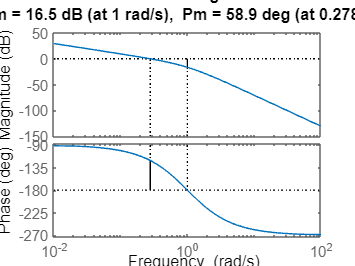

clc; clear all; close all;

s = tf('s');
G = 1/(s*(s+1)^2);

% P Controllers
C1 = 0.3;
C2 = 1;
C3 = 3;
% Open loop
L1 = C1*G;
L2 = C2*G;
L3 = C3*G;

% Bode Plot of L
margin(L1)

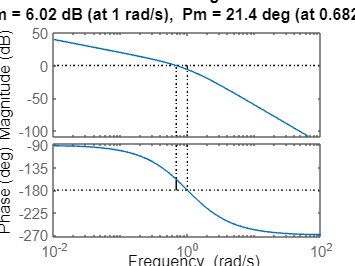

margin(L2)

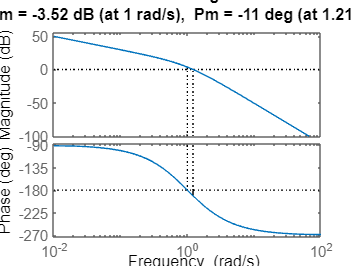

margin(L3)

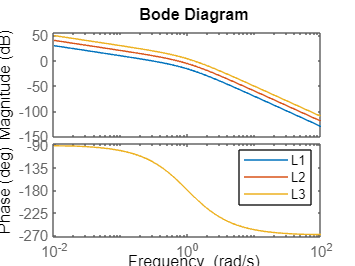

% all combined
bode(L1)
hold on
bode(L2)
hold on
bode(L3)
hold off
legend

Notice that increasing the P-gain moves the $|L\left(j\omega \right)|$ curve up which generally is a good thing because it 1) increases the bandwidth $\omega_c$ and 2) increases low frequency gain. However, increasing it too much makes the closed-loop unstable (notice negative PM for the third controller)! To get a better understanding why, look at the Nyquist plot.

## Nyquist

The Nyquist stability criterion states that $Z=P+N$. Where $Z=$ number of unstable poles of closed-loop, $P=$ number of unstable poles of open-loop, $N=$ number of encirclements of the $-1$ point. 

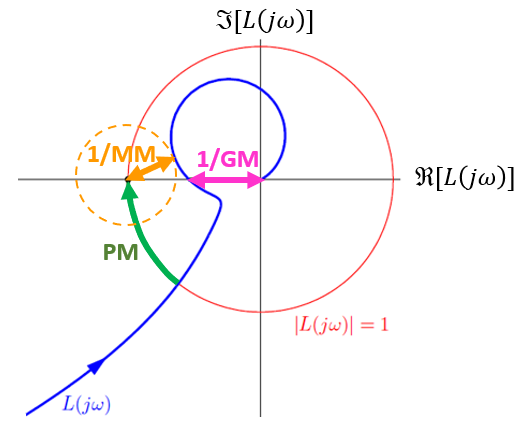

% Find P (number of unstable poles of open loop)
L1_poles = pole(L1)

L1_poles =      0
    -1
    -1


L2_poles = pole(L2)

L2_poles =      0
    -1
    -1


L3_poles = pole(L3)

L3_poles =      0
    -1
    -1


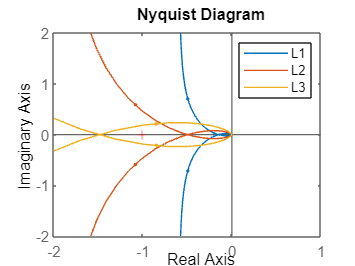


% Find N (number of encirclements of -1 point)
nyquist(L1)
hold on
nyquist(L2)
hold on
nyquist(L3)
xlim([-2,1])
ylim([-2,2])
hold off
legend


% Find Z (number of unstable poles of closed loop)
T1_poles = pole(minreal(L1/(1+L1)))

T1_poles =   -1.4542 + 0.0000i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -0.2729 + 0.3631i
  -0.2729 - 0.3631i


T2_poles = pole(minreal(L2/(1+L2)))

T2_poles =   -1.7549 + 0.0000i
  -0.1226 + 0.7449i
  -0.1226 - 0.7449i
  -1.0000 + 0.0000i
  -1.0000 - 0.0000i


T3_poles = pole(minreal(L3/(1+L3)))

T3_poles =   -2.1746 + 0.0000i
   0.0873 + 1.1713i
   0.0873 - 1.1713i
  -1.0000 + 0.0000i
  -1.0000 + 0.0000i


Notice that there are no RHP poles of $L\left(s\right)$, hence $P=0$ in all 3 cases. For the first two controllers, the contour does not encircle the $-1$ point clockwise, hence $N=0$. This means the first two systems are stable because $Z=P+N=0$. 

However, for the third controller, the contour DOES encircle the $-1$ point clockwise, hence $N=1$. This means the thid system is unstable because $Z=P+N=1$.

This can be confirmed by looking at the poles of $T\left(s\right)$ directly. Notice there is a RHP pole in $T\left(s\right)$ for the third case.

*Admittedly, using Nyquist to determine stability is much harder than just looking at the poles of *$T\left(s\right)$* directly. However, in many practical cases, finding the poles of *$T\left(s\right)$* is not possible since a parametric model of your system is not available. Hence, Nyquist is the only way to determine closed loop stability, and is a good visual tool to allow Engineers to loop shape - which we'll talk about next lecture. *

## Sensitivity: MM

The sensitivity can be used to meaure the Modulus Margin (MM). The MM is a measure of the closest point to the -1 point. 


$$\textrm{MM}=|S|_{\max }$$


A rule of thumb is that MM$\le 6$ dB

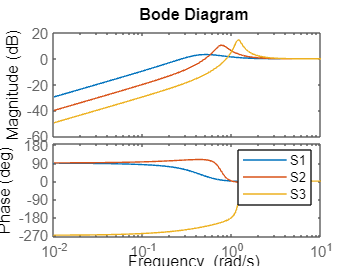

S1 = 1/(1+L1);
S2 = 1/(1+L2);
S3 = 1/(1+L3);

bode(S1)
hold on
bode(S2)
hold on
bode(S3)
hold off
legend

Notice that the third system's Nyquist contour is much closer to the -1 point than the other systems. This is why it has a higher sensitivity peak. 